clc
clear
syms q1 q2 dq1 dq2 ddq1 ddq2 m1 m2 I1 I2 L g real

Jacibians: 

oc0 = [0 0 0]';
R1 = Rz(q1)*Tx(L);
R2 = R1*Rz(q2)*Tx(L);
oc2 = R1*Rz(q2)*Tx(0.5*L);
oc2 = oc2(1:3, 4);
o1 = R1(1:3,4);
oc2 = simplify(oc2)

$$oc2 = \left(\begin{array}{c} \frac{L\,\left(\cos\left(q_{1}+q_{2}\right)+2\,\cos\left(q_{1}\right)\right)}{2}\\ \frac{L\,\left(\sin\left(q_{1}+q_{2}\right)+2\,\sin\left(q_{1}\right)\right)}{2}\\ 0 \end{array}\right)$$

o0=[0 0 0]';
oc1=[0 0 0]';
zeros=[0 0 0]';
z1 = R1(1:3,3);
z0=[0 0 1]';
Jv1 = [cross(z0,oc0) zeros]

Jv1 =      0     0
     0     0
     0     0


Jv2 = [cross(z0,oc2-o0) cross(z1,oc2-o1)]

$$Jv2 = \begin{array}{l} \left(\begin{array}{cc} -\sigma_{2} & L\,\sin\left(q_{1}\right)-\sigma_{2}\\ \sigma_{1} & \sigma_{1}-L\,\cos\left(q_{1}\right)\\ 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{L\,\left(\cos\left(q_{1}+q_{2}\right)+2\,\cos\left(q_{1}\right)\right)}{2}\\ \sigma_{2}=\frac{L\,\left(\sin\left(q_{1}+q_{2}\right)+2\,\sin\left(q_{1}\right)\right)}{2} \end{array}$$

Jw1=[z0 zeros]

Jw1 =      0     0
     0     0
     1     0


Jw2=[z0,z1]

$$Jw2 = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 1 & 1 \end{array}\right)$$

Euler Lagrange method:

q=[q1;q2];
dq = [dq1; dq2];
ddq = [ddq1; ddq2];
R1 = R1(1:3,1:3);
R2 = R2(1:3,1:3);
D1=m1*(Jv1')*Jv1 + Jw1'*R1*I1*R1'*Jw1;
D2=m2*(Jv2')*Jv2 + Jw2'*R2*I2*R2'*Jw2;
D=D1+D2;
D = simplify(D)

$$D = \left(\begin{array}{cc} I_{1}+I_{2}+\frac{5\,L^{2}\,m_{2}}{4}+L^{2}\,m_{2}\,\cos\left(q_{2}\right) & I_{2}+\frac{L^{2}\,m_{2}}{4}+\frac{L^{2}\,m_{2}\,\cos\left(q_{2}\right)}{2}\\ I_{2}+\frac{L^{2}\,m_{2}}{4}+\frac{L^{2}\,m_{2}\,\cos\left(q_{2}\right)}{2} & \frac{m_{2}\,L^{2}}{4}+I_{2} \end{array}\right)$$

% potential 
P = 9.81*oc2(2)*m2

$$P = \frac{981\,L\,m_{2}\,\left(\sin\left(q_{1}+q_{2}\right)+2\,\sin\left(q_{1}\right)\right)}{200}$$

% Gradient of potential energy
G1=diff(P,q1);
G2=diff(P,q2);
G=[G1;G2]

$$G = \left(\begin{array}{c} \frac{981\,L\,m_{2}\,\left(\cos\left(q_{1}+q_{2}\right)+2\,\cos\left(q_{1}\right)\right)}{200}\\ \frac{981\,L\,m_{2}\,\cos\left(q_{1}+q_{2}\right)}{200} \end{array}\right)$$

%Coriolis and centrofoidal force
C = Coriolis(D,q,dq,2);
C=simplify(C)

$$C = \left(\begin{array}{cc} -\frac{L^{2}\,{\mathrm{dq}}_{2}\,m_{2}\,\sin\left(q_{2}\right)}{2} & -\frac{L^{2}\,m_{2}\,\sin\left(q_{2}\right)\,\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)}{2}\\ -\frac{L^{2}\,m_{2}\,\sin\left(q_{2}\right)\,\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)}{2} & -\frac{L^{2}\,{\mathrm{dq}}_{1}\,m_{2}\,\sin\left(q_{2}\right)}{2} \end{array}\right)$$

%Equation of motion
tor = D*ddq+C*dq+G;
tor=simplify(tor)

$$tor = \begin{array}{l} \left(\begin{array}{c} {\mathrm{ddq}}_{2}\,\sigma_{2}+{\mathrm{ddq}}_{1}\,\left(I_{1}+I_{2}+\frac{5\,L^{2}\,m_{2}}{4}+\sigma_{3}\right)+\frac{981\,L\,m_{2}\,\left(\cos\left(q_{1}+q_{2}\right)+2\,\cos\left(q_{1}\right)\right)}{200}-\sigma_{1}-\frac{L^{2}\,{\mathrm{dq}}_{2}\,m_{2}\,\sin\left(q_{2}\right)\,\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)}{2}\\ {\mathrm{ddq}}_{1}\,\sigma_{2}+{\mathrm{ddq}}_{2}\,\left(\frac{m_{2}\,L^{2}}{4}+I_{2}\right)+\frac{981\,L\,m_{2}\,\cos\left(q_{1}+q_{2}\right)}{200}-\sigma_{1}-\frac{L^{2}\,{\mathrm{dq}}_{1}\,m_{2}\,\sin\left(q_{2}\right)\,\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{L^{2}\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,m_{2}\,\sin\left(q_{2}\right)}{2}\\ \sigma_{2}=I_{2}+\frac{L^{2}\,m_{2}}{4}+\frac{\sigma_{3}}{2}\\ \sigma_{3}=L^{2}\,m_{2}\,\cos\left(q_{2}\right) \end{array}$$

%substitution
D(q1,q2) = subs(D,{m1, m2, I1, I2,L },{3 4 1 2 0.4});
C(q1,q2,dq1,dq2) = subs(C*dq ,{m1, m2, I1, I2,L },{3 4 1 2 0.4});
G(q1,q2) = subs(G ,{m1, m2, I1, I2,L,g},{3 4 1 2 0.4 9.81});

Plotting

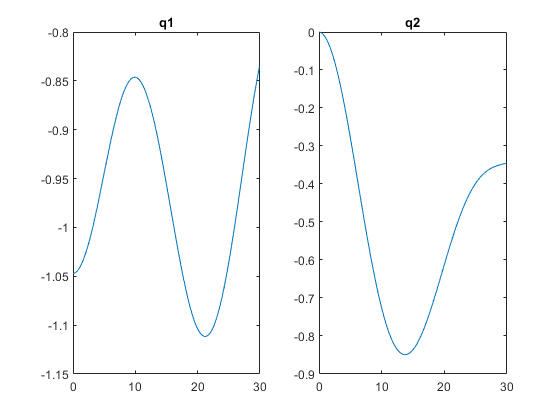

q1_0 = -pi/3;
q2_0 = 0;
dq1_0 = 0;
dq2_0 = 0;
dt=0.01;
U = [10;1];
n=300;
for i = 1:n
    
    q1p(i)=q1_0;
    q2p(i)=q2_0;
    dq1p(i)=dq1_0;
    dq2p(i)=dq2_0;
    ddq = inv(D(q1_0, q2_0))*(U-C(q1_0, q2_0,dq1_0,dq2_0)-G(q1_0,q2_0));
    ddq1p(i)=ddq(1);
    ddq2p(i)=ddq(2);
    dq1_0=dq1p(i) + double(ddq(1)*dt);
    dq2_0=dq2p(i) + double(ddq(2)*dt);
    q1_0 = q1p(i) + dq1_0*dt;
    q2_0 = q2p(i) + dq2_0*dt;
end
t = 0:0.1:(0.1*(n-1));
figure
subplot(1,2,1)
plot(t,q1p)
title('q1')
subplot(1,2,2)
plot(t,q2p)
title('q2')

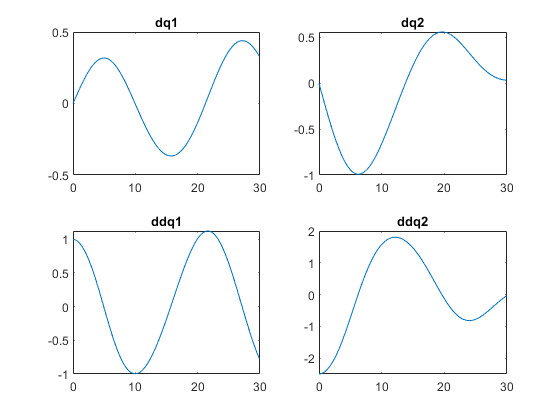

figure
subplot(2,2,1)
plot(t,dq1p)
title('dq1')
subplot(2,2,2)
plot(t,dq2p)
title('dq2')
subplot(2,2,3)
plot(t,ddq1p)
title('ddq1')
subplot(2,2,4)
plot(t,ddq2p)
title('ddq2')

Newton Euler: 